# L6 - Exercici 2 

clear all; close all; format long;

Estudiar l’error de trucament i l’error d’arroniment de la fórmula d’ordre $$O(h^2)$$, definida per 


$$$F(h)=\frac{f(x_0+h)-f(x_0-h)}{2h} $$$


en el càlcul de la derivada de la funció $$J_0(x) \: en \: x = 2$$

#### Apartat a)

Aproximeu $$J_0'(2)$$ fent ús de la fórmula F(h) , per a $$h_k=2^{-k}$$i $$k=1,2,...5$$. Calculeu l’error absolut per cada una de les aproximacions obtingudes.

k = 1:5;
hk = 2.^(-k)

hk =    0.500000000000000   0.250000000000000   0.125000000000000   0.062500000000000   0.031250000000000


x0 = 2;
J_2 = [] ;
for h = hk
    der = (besselj(0,x0+h)-besselj(0,x0 -h))./(2*h);
    J_2 = [J_2 der];
end
J_2

J_2 =   -0.560211448204116  -0.572565357792834  -0.575682991596271  -0.576464231466779  -0.576659656041451



% el valor exacte de la derivada de besselj(0,x) en x = 2 és -besselj(1,2),
% per propietats de les funcions de bessel
real = -besselj(1,2)

real =   -0.576724807756874



[ea,~,dcj2] = errores(real, J_2) %error absolut i xifres decimals correctes

ea =    0.016513359552758   0.004159449964040   0.001041816160603   0.000260576290095   0.000065151715422


dcj2 =      1     2     2     3     3


#### Apartat b)

Feu ús de la tècnica d’Extrapolació de Richardson d’ordre $$O(h^2)$$ per obtenir una aproximació  de $$J_0'(2)$$ amb més decimals correctes. Calculeu l’error absolut per cada una de les aproximacions obtingudes.

% la primera columna son els valors obtinguts amb la formula d'ordre O(h^2)
% proporcionada a l'enunciat
N1 = J_2'

N1 =   -0.560211448204116
  -0.572565357792834
  -0.575682991596271
  -0.576464231466779
  -0.576659656041451


m=length(k)

m =      5



% primera extrapolacio: segona columna
N2(2:m) =(4*N1(2:m)-N1(1:m-1))/3;
% primera extrapolacio: segona columna
N3(3:m) =N2(3:m) - (N2(3:m)-N2(2:m-1))/(4^2-1);
% segona extrapolacio: tercera columna
N4(4:m) =N3(4:m) - (N3(4:m)-N3(3:m-1))/(4^3-1);
% ultima extrapolacio
N5(5:m) =N4(5:m) - (N4(5:m)-N4(4:m-1))/(4^4-1);

richardson = [N1, N2', N3', N4', N5']

richardson =   -0.560211448204116                   0                   0                   0                   0
  -0.572565357792834  -0.576683327655739                   0                   0                   0
  -0.575682991596271  -0.576722202864083  -0.576719611183527                   0                   0
  -0.576464231466779  -0.576724644756948  -0.576724481964090  -0.576724404650113                   0
  -0.576659656041451  -0.576724797566342  -0.576724787379049  -0.576724782531193  -0.576724781049306


#### Apartat c)

Presenteu els resultats dels dos apartats previs en una mateixa taula (T1).

% el valor de J'_0(2) per la formula d'ordre O(h^2) correspon a la primera
% columna de l'extrapolació de Richardson.
extrapolacio = array2table([hk' richardson],'VariableNames',{'h_k','N1','N2','N3','N4','N5'})

extrapolacio = 5×6 table
      h_k              N1                    N2                    N3                    N4                    N5        
    _______    __________________    __________________    __________________    __________________    __________________

        0.5    -0.560211448204116                     0                     0                     0                     0
       0.25    -0.572565357792834    -0.576683327655739                     0                     0                     0
      0.125    -0.575682991596271    -0.576722202864083    -0.576719611183527                     0                     0
     0.0625    -0.576464231466779    -0.576724644756948     -0.57672448196409    -0.576724404650113                     0
    0.03125    -0.576659656041451    -


% per  al'error nomes ens interesa fixarnos en els elements de sota de la
% diagonal, ignorant els elements que son 0 per contrucció de
% l'extarpolacio de richardson
error_absolut = array2table([hk' richardson - real],'VariableNames',{'h_k','Error N1','Error N2','Error N3','Error N4','Error N5'})

error_absolut = 5×6 table
      h_k            Error N1                Error N2                Error N3                Error N4                Error N5      
    _______    ____________________    ____________________    ____________________    ____________________    ____________________

        0.5      0.0165133595527576       0.576724807756874       0.576724807756874       0.576724807756874       0.576724807756874
       0.25     0.00415944996404005    4.14801011342503e-05       0.576724807756874       0.576724807756874       0.576724807756874
      0.125     0.00104181616060284    2.60489279046983e-06    5.19657334674406e-06       0.576724807756874       0.576724807756874
     0.0625    0.000260576290094905    1.62999925668039e-07    3.25792783306689e-07    4.03106760527017e-07  

#### Apartat d)

Representeu les xifres decimals correctes en una gràfica, amb $$k=1,2,...5$$ a l’eix d’abscises. Quantes xifres decimals correctes s’obtenen en cada cas? Argumenta la teva resposta.

[~,~,dcRich,~] = errores(real, richardson)

dcRich =      1     0     0     0     0
     2     4     0     0     0
     2     5     4     0     0
     3     6     6     6     0
     3     7     7     7     7


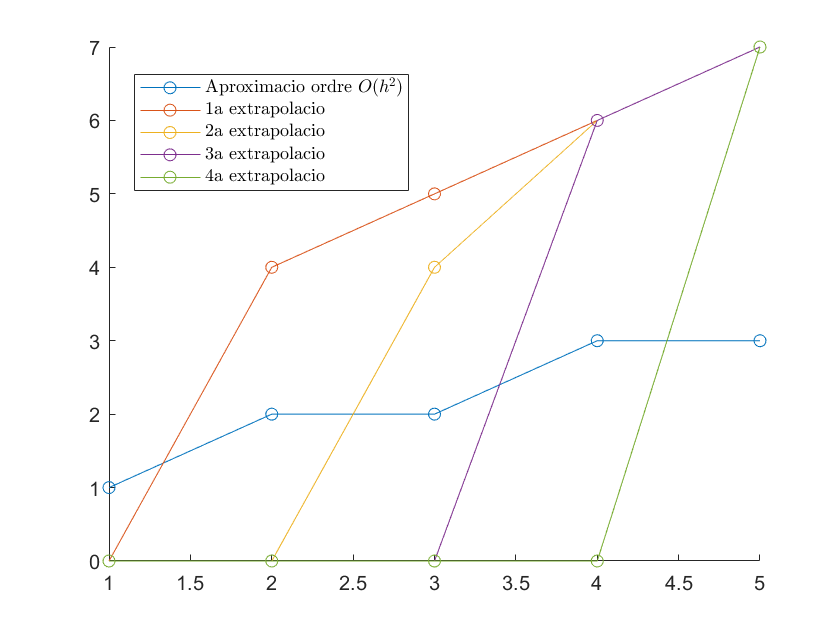


close all
% reprensentem els decimals correctes de cada una de les columnes de l'extrapolacio
% de Richarson. Per al cas de les columnes d'extrapolació (de la 1 a la 4) ,
% inicialment les xifres decimals correctes son 0 ja que encara no s'ha fet la 
% extrapolació corresponent. Un cop s'executen les extrapolacions, les
% xifres decimals correctes augmenten, tot i que no hi ha diferencia final a
% mida que s'avaça en les extrapolacions (es adir, l'ultim valor de la primera
% extrapolacio te les mateixes xifres significatives que la última extrapolacio)
hold on
plot(k,dcRich(:,1),'o-')
plot(k,dcRich(:,2),'o-')
plot(k,dcRich(:,3),'o-')
plot(k,dcRich(:,4),'o-')
plot(k,dcRich(:,5),'o-')
legend('Aproximacio ordre $O(h^2)$', '1a extrapolacio', '2a extrapolacio','3a extrapolacio','4a extrapolacio','Interpreter', 'latex', 'Location', 'best')
hold off

#### Codis auxiliars

function [ea,er,dc,xs] = errores(x,y)
% output -- error absolut, error relatiu, decimals correctes, xifres
% significatives
% input
%   x valor exacte
%   y valor aproximat
ea = abs(x-y);
er = ea./abs(x);
erp = er*100;
dc = fix(-log10(2*ea));
xs = fix(-log10(2*er));
end